# Example: Reading ADCP Data with MHKiT

The following example demonstrates a simple workflow for analyzing Acoustic Doppler Current Profiler (ADCP) data using MHKiT. MHKiT has brought the DOLfYN codebase in as an MHKiT module for working with ADCP and Acoustic Doppler Velocimeter (ADV) data. The DOLfYN MHKiT module is transferring functionality in two parts. In phase 1 the basic IO and core functions of DOLfYN are brought in. These functions include reading instrument data and rotating thru coordinate systems. In phase 2 DOLfYN analysis functions will be brought in. As phase 2 is still in progress, the analysis tools from the [DOLfYN](https://github.com/lkilcher/dolfyn) package are only available in python.

A typical ADCP data workflow is broken down into

- Review the raw data (Check timestamps, Calculate/check that the depth bin locations are correct, Look at velocity, beam amplitude and/or beam correlation data quality)

- Remove data located above the water surface or below the seafloor

- Check for spurious datapoints and remove if necessary

- If not already done within the instrument, average the data into time bins of a set time length (normally 5 to 10 min)

- Conduct further analysis as required

## Read Raw Instrument Data

The core benefit of DOLfYN is that it can read in raw data directly after transferring it off of the ADCP. The ADCP used here is a Nortek Signature1000, with the file extension '.ad2cp'. This specific dataset contains several hours worth of velocity data collected at 1 Hz from the ADCP mounted on a bottom lander in a tidal inlet. The instruments that DOLfYN supports are listed in the [docs](https://dolfyn.readthedocs.io/en/latest/about.html).

Start by reading in the raw datafile downloaded from the instrument. The read function reads the raw file and dumps the information into an matlab structure, which contains a few groups of variables:

- Velocity in the instrument-saved coordinate system (beam, XYZ, ENU)

- Beam amplitude and correlation data

- Measurements of the instrument's bearing and environment

- Orientation matrices DOLfYN uses for rotating through coordinate frames.

Matlab's binary read takes a while to complete (usually around 3 minutes for this file). Using the optional nens keyword, it is possible to only read part of the data. Reading the first 5,000 pings could be accomplished with the command below that is commented out. 

ds = dolfyn_read('data/dolfyn/Sig1000_tidal.ad2cp');

Reading file data/dolfyn/Sig1000_tidal.ad2cp


%ds = dolfyn_read('data/dolfyn/Sig1000_tidal.ad2cp','nens',5000);

To see whats in the dataset, it is recommended that users open the ds variable in the workspace. Alternatively, removing the semicolon in the above line will print the connents of ds. 

## First Steps and QC'ing Data

### 1) Set deployment Height

Because this is a Nortek instrument, the deployment software doesn't take into account the deployment height, aka where in the water column the ADCP is. The center of the first depth bin is located at a distance = deployment height + blanking distance + cell size, so the `range` coordinate needs to be corrected so that '0' corresponds to the seafloor. This can be done using the `set_range_offset` function. This same function can be used to account for the depth of a down-facing instrument below the water surface.

Note, if using a Teledyne RDI ADCP, TRDI's deployment software asks the user to enter the deployment height/depth during configuration. If needed, this can be adjusted after-the-fact using `set_range_offset` as well.

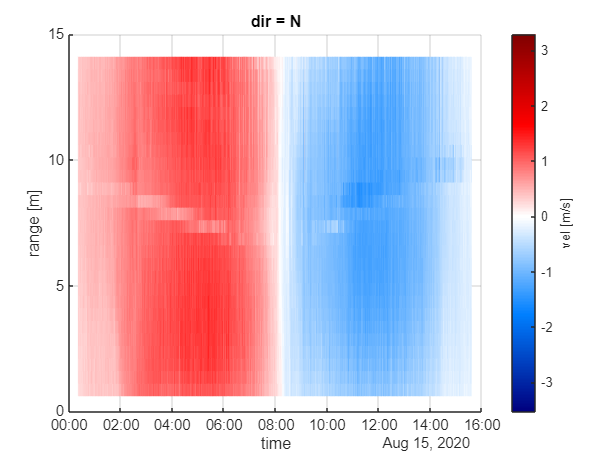

dolfyn_plot(ds,'vel','dim',2)

The ADCP transducers were measured to be 0.6 meters from the feet of the lander

ds = set_range_offset(ds, 0.6);

So, the center of bin 1 is located at 1.2 meters

ds.coords.range

ans =     1.2000    1.7000    2.2000    2.7000    3.2000    3.7000    4.2000    4.7000    5.2000    5.7000    6.2000    6.7000    7.2000    7.7000    8.2000    8.7000    9.2000    9.7000   10.2000   10.7000   11.2000   11.7000   12.2000   12.7000   13.2000   13.7000   14.2000   14.7000


### 2) Remove data beyond surface level

To reduce the amount of data the code must run through, we can remove all data at and above the water surface. Because the instrument was looking up, we can use the pressure sensor data and the function find_surface_from_P. This does require that the pressure sensor was 'zeroed' prior to deployment. If the instrument is looking down or lacks pressure data, use the function find_surface to detect the seabed or water surface.

ADCPs don't measure water salinity, so it will need to be given to the function. The returned dataset contains the an additional variable "depth". If find_surface_from_P is run after set_range_offset, depth is the distance of the water surface away from the seafloor; otherwise it is the distance to the ADCP pressure sensor.

After calculating depth, data in depth bins at and above the physical water surface can be removed using nan_beyond_surface. Note that this function returns a new dataset.

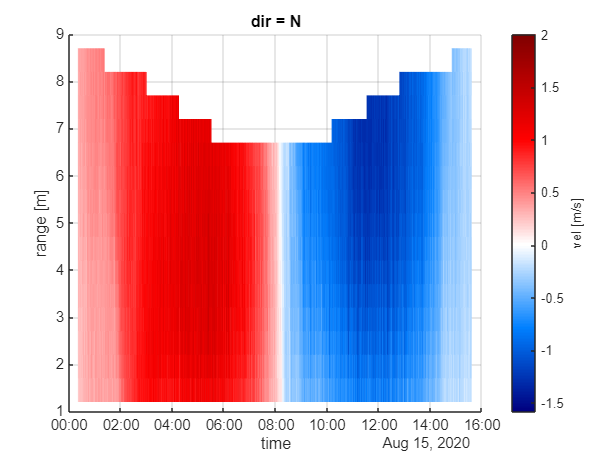

ds = find_surface_from_P(ds, 'salinity',31);
ds = nan_beyond_surface(ds);
dolfyn_plot(ds,'vel','dim',2)

### 3) Correlation Filter

Once beyond-surface bins have been removed, ADCP data is typically filtered by acoustic signal correlation to clear out spurious velocity datapoints (caused by bubbles, kelp, fish, etc moving through one or multiple beams).

We can take a quick look at the data to see about where this value should be using dolfyn_plot.

In the following code, we show data from beam 2 between a range of 0 to 9 m from the ADCP. Because we set the value of everything beyond the surface to NaN, Matlab will automatically cut off the graph when it gets to that range (in this case 9 m).

Not all ADCPs return acoustic signal correlation, which in essence is a quantitative measure of signal quality. ADCPs with older hardware do not provide a correlation measurement, so this step will be skipped with these instruments.

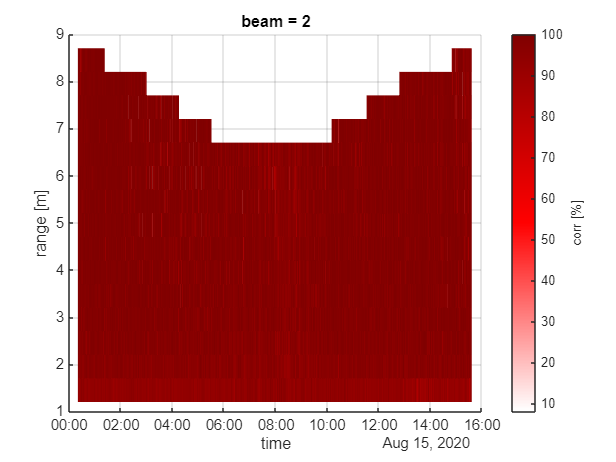

dolfyn_plot(ds,'corr','dim',2)

`It's a good idea to check the other beams as well. Much of this data is high quality, and to not lose data with low correlation caused by natural variation, we'll use the ``correlation_filter`` to set velocity values corresponding to correlations below 50% to NaN.`

`Note that this threshold is dependent on the deployment environment and instrument, and it isn't uncommon to use a value as low as 30%, or to pass on this function completely.`

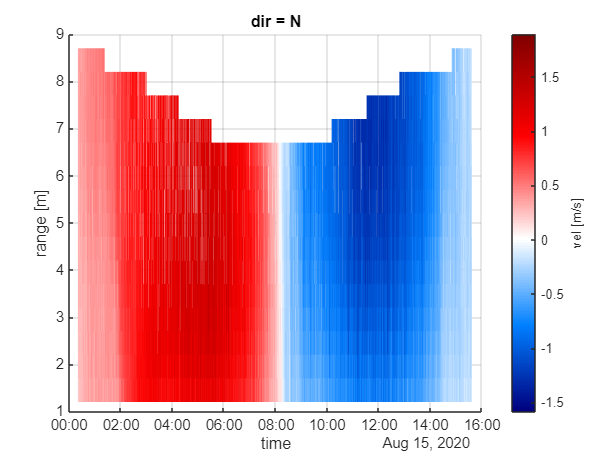

ds = correlation_filter(ds, 'thresh',50);
dolfyn_plot(ds,'vel','dim',2)

## Review the Data

Now that the data has been cleaned, the next step is to rotate the velocity data into true East, North, Up coordinates. 

ADCPs use an internal compass or magnetometer to determine magnetic ENU directions. The set_declination function takes the user supplied magnetic declination (which can be looked up online for specific coordinates) and adjusts the velocity data accordingly.

Instruments save vector data in the coordinate system specified in the deployment configuration file. To make the data useful, it must be rotated through coordinate systems ("beam"<->"inst"<->"earth"<->"principal"), done through the `rotate2` function. If the "earth" (ENU) coordinate system is specified, DOLfYN will automatically rotate the dataset through the necessary coordinate systems to get there. 

Because this ADCP data was already in the "earth" coordinate system, `rotate2` will return the input dataset. `set_declination` will run correctly no matter the coordinate system.

ds = set_declination(ds, 15.8);
ds = rotate2(ds, 'earth');

Data is already in the earth coordinate system

To rotate into the principal frame of reference (streamwise, cross-stream, vertical), if desired, we must first calculate the depth-averaged principal flow heading and add it to the dataset attributes. Then the dataset can be rotated using the same `rotate2` function. 

depth_averaged_velocity = mean(squeeze(ds.vel.data), 2);

Here we average the data over the depth or 'range'. To determine what each dimension represents, users can look at the dims field of each variable. 

ds.vel.dims

ans = 1×3 cell array
    {'time'}    {'range'}    {'dir'}


ds.attrs.principal_heading = calc_principal_heading(depth_averaged_velocity, true);
ds_streamwise = rotate2(ds, 'principal');

Because this deployment was set up in "burst mode", the next standard step in this analysis is to average the velocity data into time bins. This and other features (such as the QC mentioned above will be in the next stage of Dolfyn development). 

## Average the Data

Because this deployment was set up in "burst mode", the next standard step in this analysis is to average the velocity data into time bins. 

If an instrument was set up to record velocity data in an "averaging mode" (a specific profile and/or average interval, e.g. take an average of 5 minutes of data every 30 minutes), this step was completed within the ADCP during deployment and can be skipped.

To average the data into time bins (aka ensembles), start by initiating the binning tool VelBinner. "n_bin" is the number of data points in each ensemble, in this case 300 seconds worth of data, and "fs" is the sampling frequency, which is 1 Hz for this deployment. Once initiated, average the data into ensembles using the binning tool's bin_average function.

## Saving and Loading Dolfyn datasets

Datasets can be saved and loaded using the write_netcdf and read_netcdf functions, respectively. 

% Uncomment these lines to save and load to your current working directory
% write_netcdf(ds, 'your_data.nc');
% ds_saved = read_netcdf('your_data.nc');